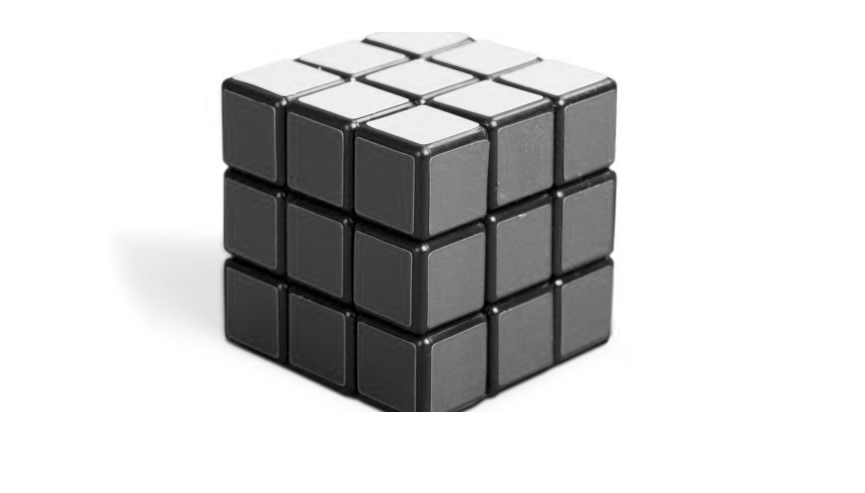

filt =      1     2     1
     0     0     0
    -1    -2    -1


im = imread("cube.jpg");
im = im(:,:,2);
imshow(im);

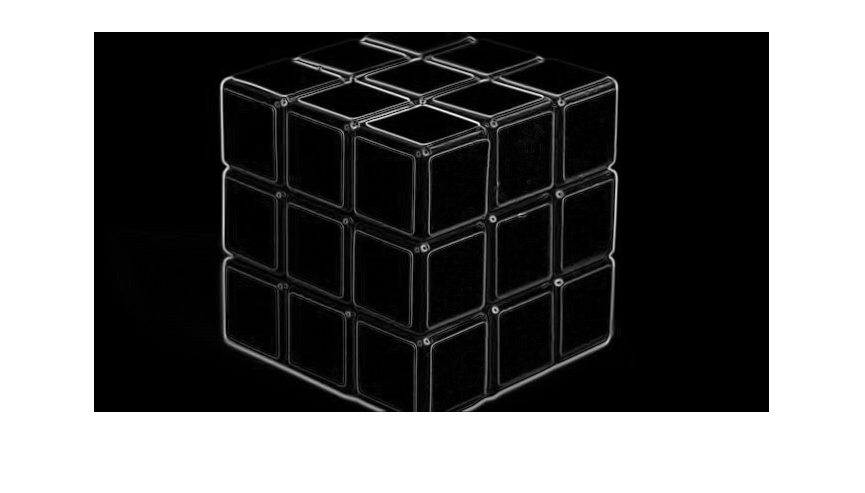

outim1 = imgradient(double(im),'sobel');
imshow(outim1,[]);

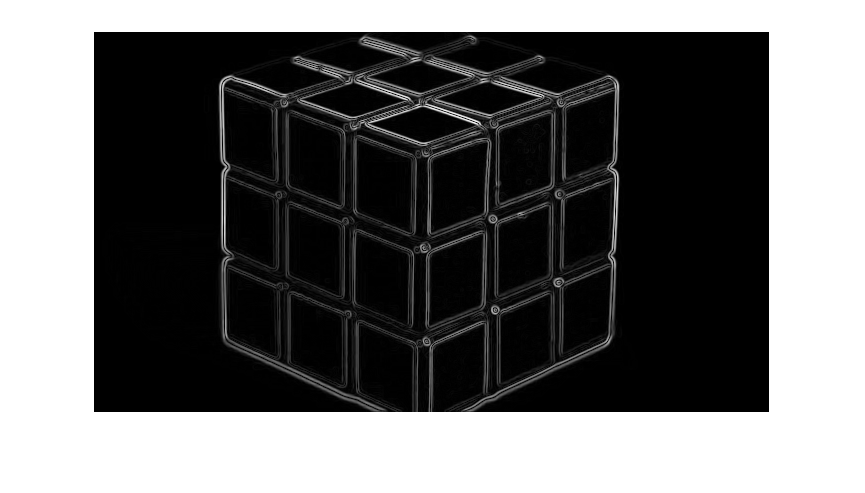

outim2 = imgradient(double(outim1),'sobel');
imshow(outim2,[]);

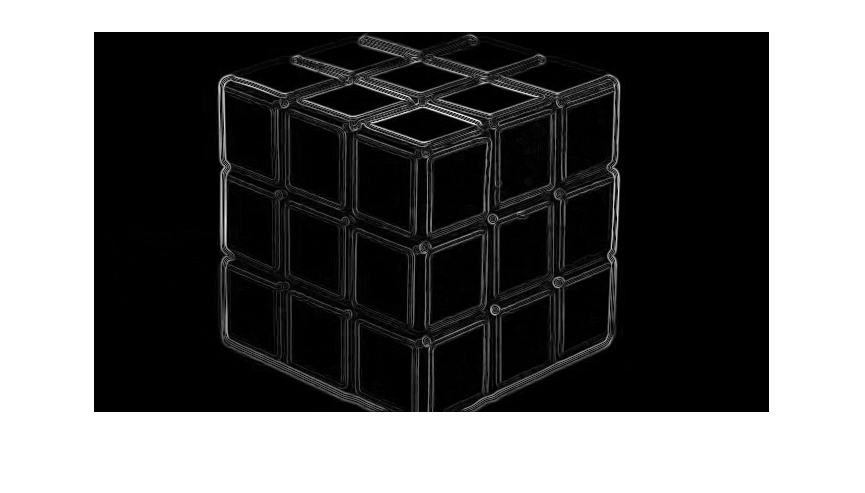

outim3 = imgradient(double(outim2),'sobel');
imshow(outim3,[]);


filt = fspecial('sobel')

filt =      1     2     1
     0     0     0
    -1    -2    -1


outx = imfilter(double(im), filt)

outx =         -765       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020
           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0        

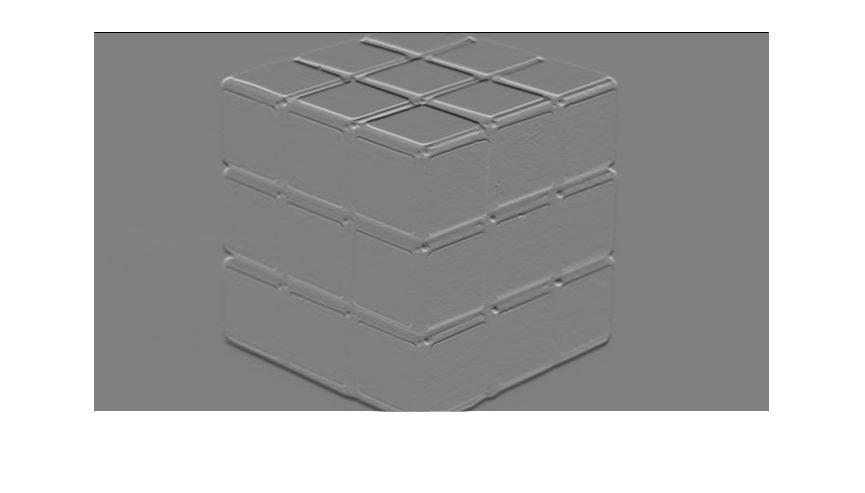

imshow(outx, [0,255]);

outy = imfilter(double(im), filt')

outy =         -765           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
       -1020           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0        

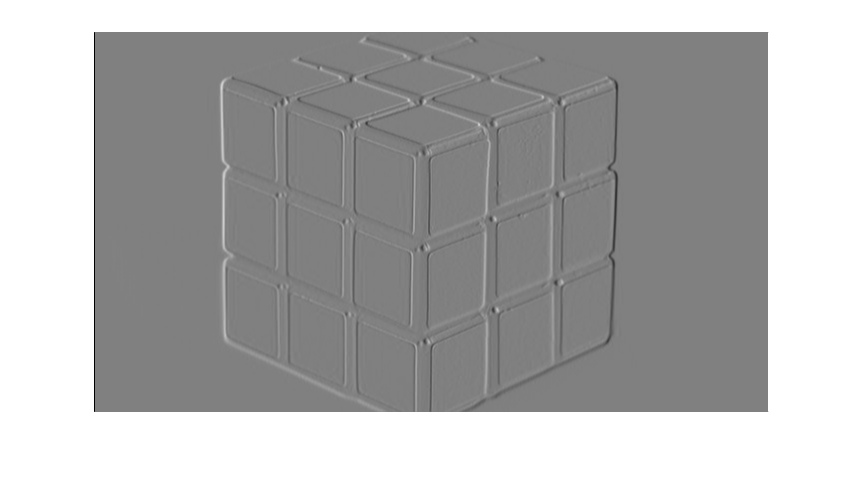

imshow(outy, [0.255]);

out = outx.^2 + outy.^2 

out =      1170450     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400     1040400
     1040400           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0         

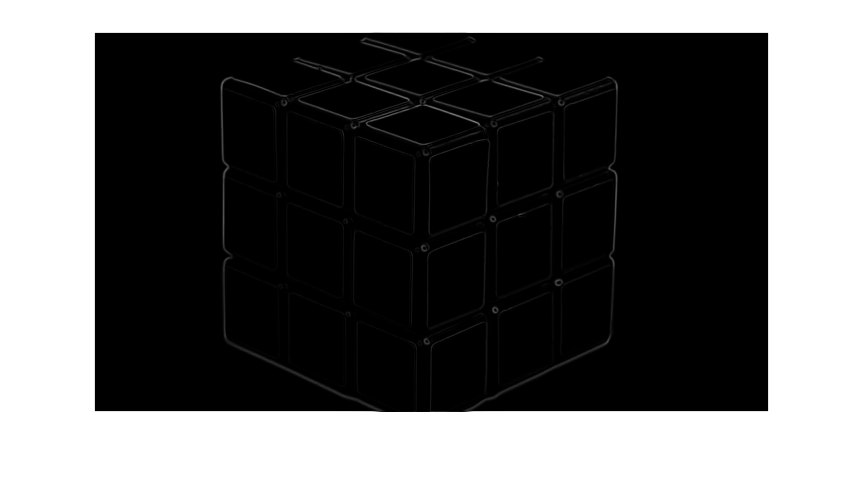

imshow(out, []);

img = imread("zebrabw.jpg");
img = img(:,:,1);
img = double(img)./255

img =     0.4706    0.4745    0.4784    0.4824    0.4863    0.4902    0.4941    0.4980    0.5137    0.5020    0.4980    0.4863    0.4706    0.4902    0.5059    0.4941    0.4980    0.7922    0.9176    0.9804    0.9333    0.6549    0.4039    0.3098    0.3451    0.2863    0.5412    0.8784    0.4980    0.3804    0.6549    0.7686    0.8275    0.7333    0.7451    0.7412    0.6353    0.6118    0.6000    0.4902    0.4510    0.4510    0.3608    0.2627    0.2627    0.3647    0.5647    0.7647    0.7843    0.8471
    0.4706    0.4745    0.4784    0.4824    0.4863    0.4902    0.4941    0.4980    0.5098    0.5059    0.5059    0.4941    0.4824    0.4902    0.5059    0.5059    0.6431    0.8863    0.9765    0.9843    0.8549    0.5373    0.3333    0.2902    0.3412    0.2549    0.5137    0.9216    0.5882    0.2706    0.4353    0.6902    0.8431    0.7686    0.7765    0.7882    0.7059    0.6627    0.6627    0.6275    0.6235    0.6039    0.5333    0.5098    0.5804    0.6627    0.7373    0.8235    0.9569   

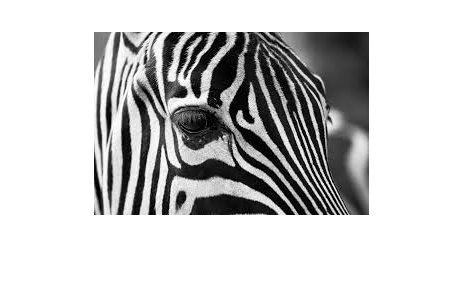

imshow(img);

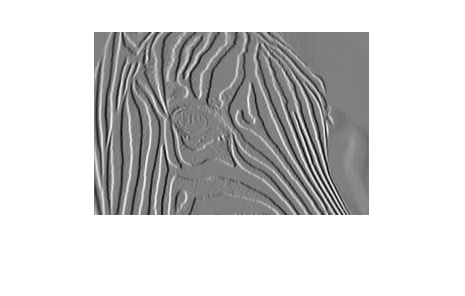

[gx, gy] = imgradientxy(img, 'sobel');
imshow((gx+4)/8);

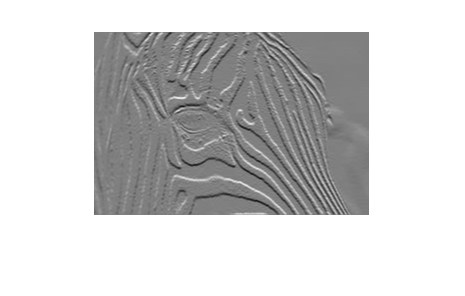

imshow((gy+4)/8);

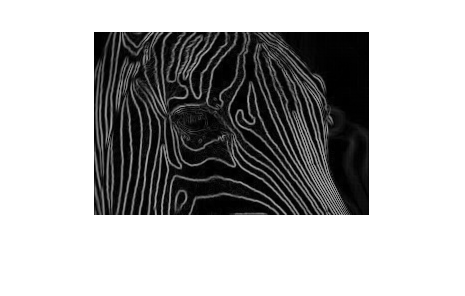

gmag = sqrt(gx.^2 + gy.^2);
imshow(gmag/(4 * sqrt(2)));

gmagsmooth = imgaussfilt(gmag,0.5)

gmagsmooth =     0.0170    0.0296    0.0317    0.0320    0.0318    0.0314    0.0355    0.0633    0.0308    0.0490    0.0702    0.1002    0.0539    0.1071    0.0694    0.3499    1.2808    1.4958    0.7185    0.3244    1.4175    1.9884    1.2644    0.3113    0.2060    0.8814    2.0389    0.6374    1.8002    0.8259    1.5401    1.0440    0.2149    0.2783    0.1943    0.4155    0.5193    0.3333    0.4974    0.6880    0.7078    0.8073    1.0110    1.1013    1.3355    1.5299    1.4676    1.0032    0.6072    0.4519
    0.0139    0.0280    0.0344    0.0367    0.0355    0.0318    0.0321    0.0560    0.0449    0.0431    0.0816    0.1142    0.0756    0.0930    0.1646    0.7224    1.5365    1.3659    0.5902    0.6299    1.7485    2.0187    1.0864    0.2894    0.2655    0.9407    2.1794    0.8170    2.1510    1.2044    1.8314    1.6527    0.6478    0.2670    0.1435    0.3172    0.4798    0.3255    0.4220    0.7182    0.9490    1.0895    1.2511    1.4772    1.7381    1.6820    1.3460    0.9212    0.

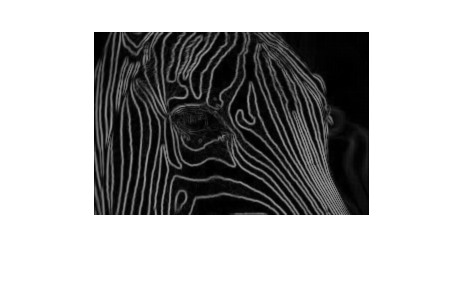

imshow(gmagsmooth/(4 * sqrt(2)));

M = max(gmagsmooth,[],'all')

M = 3.3380

% someThresholdValue = 



binaryImage = gmagsmooth > 2

binaryImage = 183×275 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0

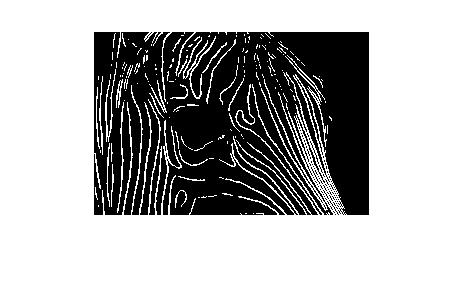

imshow(binaryImage,[])

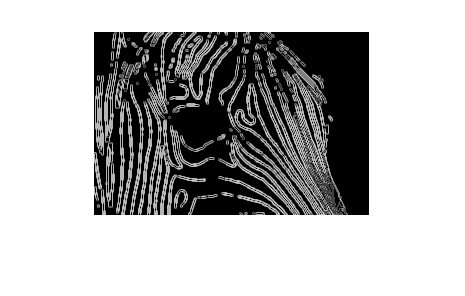


[gx2,gy2 ] = imgradientxy(binaryImage, 'sobel');

gmag2 = sqrt(gx2.^2 + gy2.^2);
imshow(gmag2/(4 * sqrt(2)));




[gx3,gy3 ] = imgradientxy(gmag2, 'sobel')

gx3 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.4142    7.0711    6.0000   -0.8284   -7.4142   -6.2426   16.0000         0   -5.0990    8.0000   -3.4961   -8.0000   -7.4049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    5.9907    8.4853    2.0000   -1.6569   -7.9907   -6.8284   16.0000         0  -10.0093    6.0000    5.7481   -6.0000  -11.7388         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

gy3 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.4142    4.2426    3.6569    0.8284    0.5858    0.5858         0         0   -1.7481   -3.4961   -0.0000    3.4961    1.7481         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    3.1623    6.3246    4.3246    2.3246    1.1623         0         0         0   -3.1623   -8.3246   -4.5765    3.1716    2.5858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

M1 = min(gx3,[],'all')

M1 = -17.8885

M2 = min(gy3,[],'all')

M2 = -17.8885


[gmag3, gdir ] = imgradient(gx3, gy3)

gmag3 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    2.0000    8.2462    7.0266    1.1716    7.4373    6.2701   16.0000         0    5.3903    8.7306    3.4961    8.7306    7.6085         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    6.7741   10.5830    4.7646    2.8546    8.0748    6.8284   16.0000         0   10.4970   10.2615    7.3474    6.7867   12.0202         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

gdir =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  -45.0000  -30.9638  -31.3613 -135.0000 -175.4825 -174.6393         0         0  161.0768   23.6061  180.0000 -156.3939 -166.7175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  -27.8280  -36.6992  -65.1806 -125.4798 -171.7242 -180.0000         0         0  162.4669   54.2175   38.5261 -152.1393 -167.5774         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  


min(gmag3, [], 'all')

ans = 0

max(gmag3, [], 'all')

ans = 18.6956

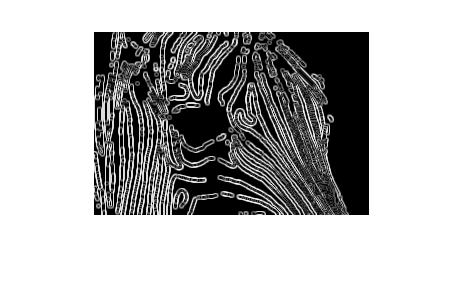


imshow(gmag3, []);

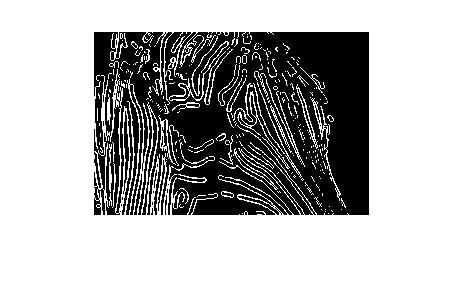


binaryfinal = gmag3 > 10 ; 

imshow(binaryfinal,[]);



% gmag3 = sqrt(gx3.^2 + gy3.^2);
% imshow(gmag2/(4 * sqrt(2)));


